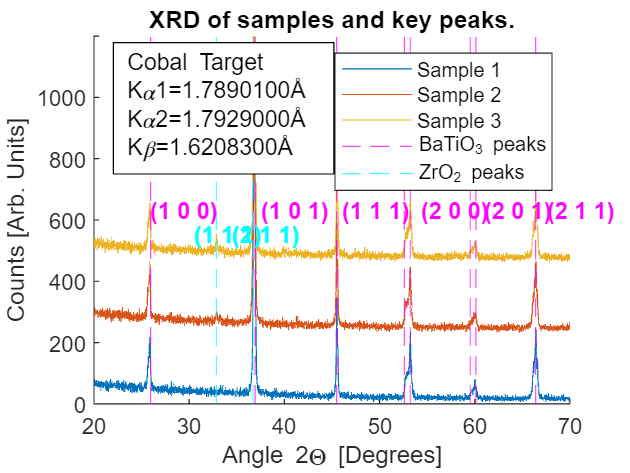

%clear crap
clear all

%importing data
data_1 = readtable("Year 3/AIT/SAMPLE1_XRD.csv");
data_2 = readtable("Year 3/AIT/SAMPLE2_XRD.csv");
data_3 = readtable("Year 3/AIT/SAMPLE3_XRD.csv");

%extracting x & y coordinates
x_1 = table2array(data_1(:,1));
y_1 = table2array(data_1(:,2));
x_2 = table2array(data_2(:,1));
y_2 = table2array(data_2(:,2));
x_3 = table2array(data_3(:,1));
y_3 = table2array(data_3(:,2));

%skewing data of samples 2 & 3 so that graph is readable.
y_2 = y_2 + 225;
y_3 = y_3 + 450;

%plotting data
figure = plot(x_1,y_1);
hold on %plotting on the same graph
figure = plot(x_2,y_2);
figure = plot(x_3,y_3);

%plotting vertical lines
%first two are ordered in this way to ensure legend works
xline(25.956,"--m") %BaTiO3
xline(32.85,"--c") %ZrO2

%plotting subsequent vertical lines
xline(36.920,"--m") %BaTiO3
xline(36.7,"--c") %ZrO2
xline(45.482,"--m") %BaTiO3
xline(52.596,"--m") %BaTiO3
xline(53.221,"--m") %BaTiO3
xline(59.524,"--m") %BaTiO3
xline(60.112,"--m") %BaTiO3
xline(66.382,"--m") %BaTiO3

%adding annotation
dim = [.18 .1 .9 .81];

str = {["Cobalt Target"],
    ["K{\alpha}1=1.7890100" + char(197)],
    ["K{\alpha}2=1.7929000" + char(197)],
    ["K{\beta}=1.6208300" + char(197)]
    };
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.BackgroundColor="White";


%Adding miller indeces BaTiO3
dim = [.22 .1 .9 .5];
str = {["(1 0 0)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="magenta";
ann.FontWeight="bold";

dim = [.395 .1 .9 .5];
str = {["(1 0 1)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="magenta";
ann.FontWeight="bold";

dim = [.525 .1 .9 .5];
str = {["(1 1 1)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="magenta";
ann.FontWeight="bold";

dim = [.65 .1 .9 .5];
str = {["(2 0 0)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="magenta";
ann.FontWeight="bold";

dim = [.75 .1 .9 .5];
str = {["(2 0 1)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="magenta";
ann.FontWeight="bold";

dim = [.85 .1 .9 .5];
str = {["(2 1 1)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="magenta";
ann.FontWeight="bold";

%Adding miller indeces ZrO2
dim = [.29 .1 .9 .45];
str = {["(1 1 1)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="cyan";
ann.FontWeight="bold";

dim = [.35 .1 .9 .45];
str = {["(2 1 1)"]};
ann = annotation('textbox',dim,'String',str,'FitBoxToText','on');
ann.EdgeColor="none";
ann.Color="cyan";
ann.FontWeight="bold";

%labelling graph
xlabel("Angle 2{\Theta} [Degrees]");
ylabel("Counts [Arb. Units]");
title("XRD of samples and key peaks.")
legend("Sample 1", ...
    "Sample 2", ...
    "Sample 3", ...
    "BaTiO{_3} peaks", ...
    "ZrO{_2} peaks",...
    "Location","NorthEast")
ylim([0 1200])
yticklabels({'0','200','400','600','800','1000'})

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

hold off %ending plot 